# Likelihood vs CSB: pendulum example

clear;clc
syms x_1(t) x_2(t) m f g l u(t) %symbolic state variables and parameters
u(t)=1;
%Defining the system of differential equations
ode1 = diff(x_1) == x_2;
ode2 = diff(x_2) == -f*x_2/m - g*sin(x_1)/l + u(t)/(m*l);
%Array with the system
odes=[ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=\frac{1}{l\,m}-\frac{f\,x_{2}\left(t\right)}{m}-\frac{g\,\sin\left(x_{1}\left(t\right)\right)}{l} \end{array}\right)$$

%choose an order for state variables
vars = [x_1 x_2];
domain=[0 100];%rango numérico en el que se solucionará el sistema
modelName='pend';%nombre para el archivo de modelo
gsua_dataprep(odes,vars,domain,modelName);%consultamos el orden para introducir los parámetros

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans = \left(\begin{array}{cccccc} x_{1}\left(t\right) & x_{2}\left(t\right) & f & g & l & m \end{array}\right)$$

Ranges=[-1 1;-1 1;0 1; 9.5 10.5; 2 4; 3 7];%generamos rangos para dicho orden
T = gsua_dataprep(odes,vars,domain,modelName,'range',Ranges)%generamos la tabla del sistema

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans = \left(\begin{array}{cccccc} x_{1}\left(t\right) & x_{2}\left(t\right) & f & g & l & m \end{array}\right)$$

T = 6×2 table
               Range       Nominal
            ___________    _______

    x_10     -1       1        0  
    x_20     -1       1        0  
    f         0       1      0.5  
    g       9.5    10.5       10  
    l         2       4        3  
    m         3       7        5  


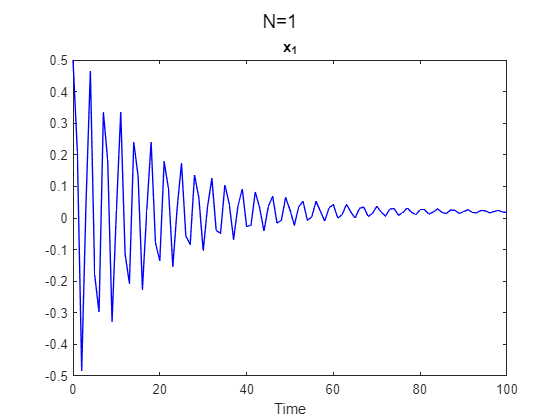

T.Properties.CustomProperties.output=1;
T.Nominal=[0.5 0.5 0.5 9.8 3 5]';
xdata=0:1:100;
gsua_eval(T.Nominal,T,xdata);

Tia=gsua_likelihood(T,xdata,[],0.95,0.1,1.3,0.5,0.001,100,1,true,false,true,[]);

Generating a valid matrix for estimations
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Generating a valid matrix for estimations
Estimation 1

Local minimum possible. Co

Mia=gsua_dmatrix(Tia,500);
ydata=gsua_eval(T.Nominal,T);

%gsua_ua(Mia,Tia,'parallel',false,'ynom',ydata);

Sim500 Done
Sim499 Done
Sim498 Done
Sim497 Done
Sim496 Done
Sim495 Done
Sim494 Done
Sim493 Done
Sim492 Done
Sim491 Done
Sim490 Done
Sim489 Done
Sim488 Done
Sim487 Done
Sim486 Done
Sim485 Done
Sim484 Done
Sim483 Done
Sim482 Done
Sim481 Done
Sim480 Done
Sim479 Done
Sim478 Done
Sim477 Done
Sim476 Done
Sim475 Done
Sim474 Done
Sim473 Done
Sim472 Done
Sim471 Done
Sim470 Done
Sim469 Done
Sim468 Done
Sim467 Done
Sim466 Done
Sim465 Done
Sim464 Done
Sim463 Done
Sim462 Done
Sim461 Done
Sim460 Done
Sim459 Done
Sim458 Done
Sim457 Done
Sim456 Done
Sim455 Done
Sim454 Done
Sim453 Done
Sim452 Done
Sim451 Done
Sim450 Done
Sim449 Done
Sim448 Done
Sim447 Done
Sim446 Done
Sim445 Done
Sim444 Done
Sim443 Done
Sim442 Done
Sim441 Done
Sim440 Done
Sim439 Done
Sim438 Done
Sim437 Done
Sim436 Done
Sim435 Done
Sim434 Done
Sim433 Done
Sim432 Done
Sim431 Done
Sim430 Done
Sim429 Done
Sim428 Done
Sim427 Done
Sim426 Done
Sim425 Done
Sim424 Done
Sim423 Done
Sim422 Done
Sim421 Done
Sim420 Done
Sim419 Done
Sim418 Done
Sim4

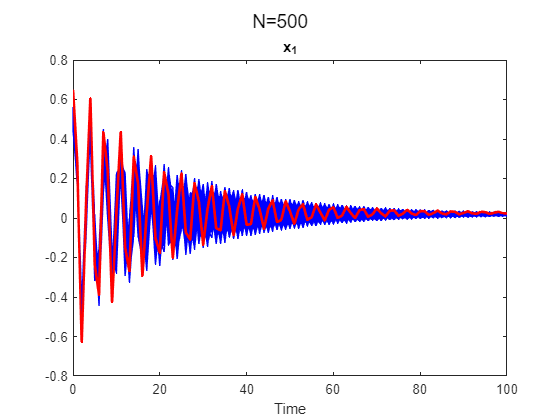

ydata2=ydata*1.3;
yia=gsua_eval(Mia',Tia,0:100,ydata2);

Toat=gsua_oatr(T)

Tcsb=gsua_csb(Toat,5e3,'protect',true);

Sim500 Done
Sim499 Done
Sim498 Done
Sim497 Done
Sim496 Done
Sim495 Done
Sim494 Done
Sim493 Done
Sim492 Done
Sim491 Done
Sim490 Done
Sim489 Done
Sim488 Done
Sim487 Done
Sim486 Done
Sim485 Done
Sim484 Done
Sim483 Done
Sim482 Done
Sim481 Done
Sim480 Done
Sim479 Done
Sim478 Done
Sim477 Done
Sim476 Done
Sim475 Done
Sim474 Done
Sim473 Done
Sim472 Done
Sim471 Done
Sim470 Done
Sim469 Done
Sim468 Done
Sim467 Done
Sim466 Done
Sim465 Done
Sim464 Done
Sim463 Done
Sim462 Done
Sim461 Done
Sim460 Done
Sim459 Done
Sim458 Done
Sim457 Done
Sim456 Done
Sim455 Done
Sim454 Done
Sim453 Done
Sim452 Done
Sim451 Done
Sim450 Done
Sim449 Done
Sim448 Done
Sim447 Done
Sim446 Done
Sim445 Done
Sim444 Done
Sim443 Done
Sim442 Done
Sim441 Done
Sim440 Done
Sim439 Done
Sim438 Done
Sim437 Done
Sim436 Done
Sim435 Done
Sim434 Done
Sim433 Done
Sim432 Done
Sim431 Done
Sim430 Done
Sim429 Done
Sim428 Done
Sim427 Done
Sim426 Done
Sim425 Done
Sim424 Done
Sim423 Done
Sim422 Done
Sim421 Done
Sim420 Done
Sim419 Done
Sim418 Done
Sim4

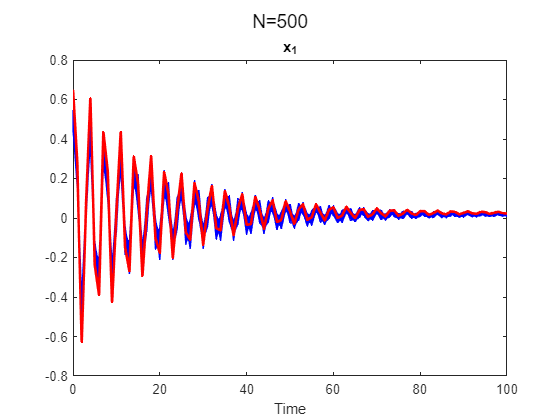

Mcsb=gsua_dmatrix(Tcsb,500);
ycsb=gsua_eval(Mcsb',T,xdata,ydata2);

Jia = gsua_costfMulti(yia,ydata,0.3,false);
Jcsb = gsua_costfMulti(ycsb,ydata,0.3,false);
Jtest=gsua_costfMulti(ydata2,ydata,0.3,false)

Jtest = 1

[Jia2,orderia]=sort(Jia);
[Jcsb2,ordercsb]=sort(Jcsb);
supia=find(Jia2 < 1, 1, 'last' ); 
supcsb=find(Jcsb2 < 1, 1, 'last' ); 

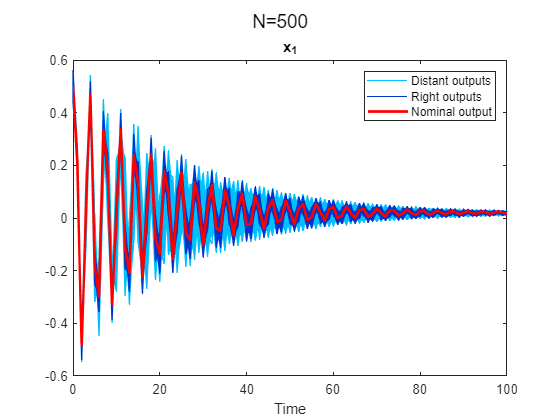

gsua_plot('UncertaintyAnalysis',T,yia(orderia,:,:),xdata,ydata,supia);

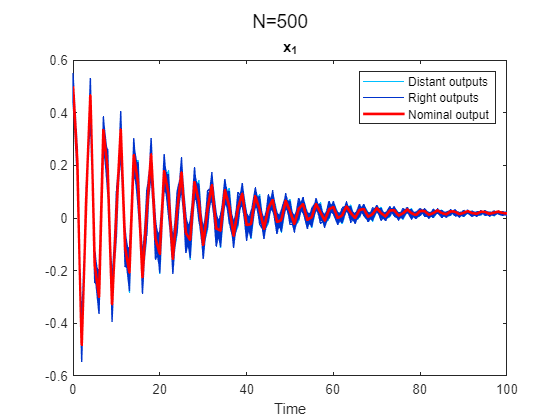

gsua_plot('UncertaintyAnalysis',T,ycsb(ordercsb,:,:),xdata,ydata,supcsb);

%Tcsb2=gsua_csb(Toat,5e3,'protect',true,'margin',);
Tcsb

Tcsb = 6×2 table
                  Range           Nominal
            __________________    _______

    x_10    0.44494     0.5492      0.5  
    x_20    0.38857    0.59151      0.5  
    f        0.4843    0.64345      0.5  
    g        9.7071     9.8955      9.8  
    l        2.9693     3.0338        3  
    m        4.5979     5.9365        5  


Tia

Tia = 6×2 table
                  Range           Nominal
            __________________    _______

    x_10    0.44375     0.5625      0.5  
    x_20     0.4625    0.53125      0.5  
    f         0.425    0.56797      0.5  
    g           9.5     10.147      9.8  
    l        2.9047     3.2172        3  
    m           4.3        5.6        5  
